# Debug Ward Construction

This script helps debug why fields might be zero or too small

clear; close all; clc;

fprintf('Debugging Ward Construction\n');

Debugging Ward Construction


fprintf('==========================\n\n');

## Step 1: Test Twistor Function

fprintf('Step 1: Testing Twistor Function\n');

Step 1: Testing Twistor Function


fprintf('---------------------------------\n');

---------------------------------



% Create test field
test_field = mlraut.TwistorMaxwellField('gauge_group', 'U1', ...
                                 'n_points', 10, ...
                                 'x_range', [-2, 2], ...
                                 'slice_type', 'euclidean');

% Set simple twistor function
test_field.setSimpleTwistorFunction();

% Test twistor function at various points
test_points = [
    1, 0, 1, 0;
    0, 1, 0, 1;
    1, 1, 0, 0;
    0.5, 0.5, 0.5, 0.5;
    1, 0, 0, 1
];

fprintf('Twistor function values at test points:\n');

Twistor function values at test points:


for i = 1:size(test_points, 1)
    W = test_points(i, :)';
    g_val = test_field.twistor_function(W);
    fprintf('  W = [%.1f, %.1f, %.1f, %.1f] -> g = %.3f + %.3fi (|g| = %.3f)\n', ...
            W(1), W(2), W(3), W(4), real(g_val), imag(g_val), abs(g_val));
end

  W = [1.0, 0.0, 1.0, 0.0] -> g = -0.600 + -0.935i (|g| = 1.111)
  W = [0.0, 1.0, 0.0, 1.0] -> g = 10.000 + 0.000i (|g| = 10.000)
  W = [1.0, 1.0, 0.0, 0.0] -> g = 10.000 + 0.000i (|g| = 10.000)
  W = [0.5, 0.5, 0.5, 0.5] -> g = -2.194 + -1.199i (|g| = 2.500)
  W = [1.0, 0.0, 0.0, 1.0] -> g = 10.000 + 0.000i (|g| = 10.000)


## Step 2: Test Gauge Potential at Single Point

fprintf('\n\nStep 2: Testing Gauge Potential Computation\n');



Step 2: Testing Gauge Potential Computation


fprintf('--------------------------------------------\n');

--------------------------------------------



% Test at origin
x_test = [0, 0, 0, 0];  % Euclidean space point
A_mu = test_field.computeGaugePotentialAtPoint(x_test);

fprintf('Gauge potential at origin: A = [%.3e, %.3e, %.3e, %.3e]\n', ...
        A_mu(1), A_mu(2), A_mu(3), A_mu(4));

Gauge potential at origin: A = [-9.676e-09, -4.118e+00, -1.132e-08, 2.500e+00]


fprintf('Magnitude: |A| = %.3e\n', norm(A_mu));

Magnitude: |A| = 4.817e+00


## Step 3: Check Intermediate Values in CP¹ Integration

fprintf('\n\nStep 3: Detailed CP¹ Integration\n');



Step 3: Detailed CP¹ Integration


fprintf('---------------------------------\n');

---------------------------------



% Manually perform the integration with diagnostics
x_matrix = zeros(2, 2);  % Origin in Euclidean space
n_points_contour = 8;
zeta_vals = exp(2*pi*1i*(0:n_points_contour-1)/n_points_contour);

fprintf('Contour integration points:\n');

Contour integration points:


for k = 1:min(4, n_points_contour)
    zeta = zeta_vals(k);
    pi_A_prime = [1; zeta] / sqrt(1 + abs(zeta)^2);
    omega_A = 1i * x_matrix * pi_A_prime;
    W = [omega_A; pi_A_prime];
    
    g_val = test_field.twistor_function(W);
    fprintf('  k=%d: ζ=%.2f+%.2fi, |g|=%.3e, arg(g)=%.3f\n', ...
            k, real(zeta), imag(zeta), abs(g_val), angle(g_val));
end

  k=1: ζ=1.00+0.00i, |g|=1.647e+00, arg(g)=-2.434
  k=2: ζ=0.71+0.71i, |g|=1.647e+00, arg(g)=-2.434
  k=3: ζ=0.00+1.00i, |g|=1.647e+00, arg(g)=-2.434
  k=4: ζ=-0.71+0.71i, |g|=1.647e+00, arg(g)=-2.434


## Step 4: Test Simple Direct Implementation

fprintf('\n\nStep 4: Simple Direct Field Test\n');



Step 4: Simple Direct Field Test


fprintf('---------------------------------\n');

---------------------------------



% Create field with direct simple implementation
simple_field = mlraut.TwistorMaxwellField('gauge_group', 'U1', ...
                                   'n_points', 15, ...
                                   'x_range', [-3, 3], ...
                                   'slice_type', 'euclidean');

% Override the twistor function with something very simple
simple_field.twistor_function = @(W) simpleTestTwistor(W);

% Compute fields
simple_field.computeGaugeFields();

% Check magnitudes
E_mag = sqrt(simple_field.field_strength.Ex.^2 + ...
             simple_field.field_strength.Ey.^2 + ...
             simple_field.field_strength.Ez.^2);
B_mag = sqrt(simple_field.field_strength.Bx.^2 + ...
             simple_field.field_strength.By.^2 + ...
             simple_field.field_strength.Bz.^2);

fprintf('Field magnitudes:\n');

Field magnitudes:


fprintf('  Max |E| = %.3e\n', max(E_mag(:)));

  Max |E| = 0.000e+00


fprintf('  Max |B| = %.3e\n', max(B_mag(:)));

  Max |B| = 0.000e+00


fprintf('  Mean |E| = %.3e\n', mean(E_mag(:)));

  Mean |E| = 0.000e+00


fprintf('  Mean |B| = %.3e\n', mean(B_mag(:)));

  Mean |B| = 0.000e+00


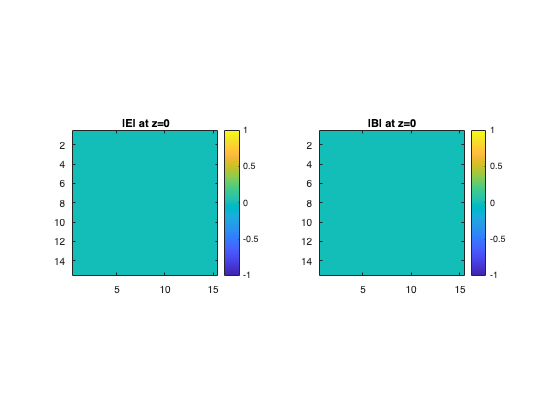


% Visualize
figure('Name', 'Debug: Field Magnitudes');
subplot(1, 2, 1);
mid = floor(simple_field.n_points/2);
imagesc(E_mag(:, :, mid));
colorbar; title('|E| at z=0');
axis equal tight;

subplot(1, 2, 2);
imagesc(B_mag(:, :, mid));
colorbar; title('|B| at z=0');
axis equal tight;

## Step 5: Test Alternative Gauge Construction

fprintf('\n\nStep 5: Alternative Construction Test\n');



Step 5: Alternative Construction Test


fprintf('-------------------------------------\n');

-------------------------------------



% Try a more direct approach for comparison
alt_field = mlraut.TwistorMaxwellField('gauge_group', 'U1', ...
                                'n_points', 20, ...
                                'x_range', [-4, 4], ...
                                'slice_type', 'euclidean');

% Use built-in monopole function
alt_field.twistor_function = @(W) monopoleTestTwistor(W);

% Override computeGaugeFields with simpler version for testing
alt_field.gauge_potential.A0 = zeros(20, 20, 20);
alt_field.gauge_potential.A1 = zeros(20, 20, 20);
alt_field.gauge_potential.A2 = zeros(20, 20, 20);
alt_field.gauge_potential.A3 = zeros(20, 20, 20);

% Simple monopole gauge potential (known to be self-dual)
[X, Y, Z] = meshgrid(linspace(-4, 4, 20));
R = sqrt(X.^2 + Y.^2 + Z.^2 + 0.1);

% Dirac monopole in appropriate gauge
alt_field.gauge_potential.A1 = -Y ./ (R .* (R + Z));
alt_field.gauge_potential.A2 = X ./ (R .* (R + Z));
alt_field.gauge_potential.A3 = zeros(size(X));

% Compute field strength
alt_field.computeFieldStrength();

% Check self-duality
fprintf('\nDirect monopole construction:\n');


Direct monopole construction:


is_sd = alt_field.checkSelfDuality();

Field is not self-dual (relative residual: 1.00e+00)
  |F_01 - F_23|/|F| = 2.80e-01
  |F_02 + F_13|/|F| = 2.80e-01
  |F_03 - F_12|/|F| = 4.41e-01


## Summary

fprintf('\n\nDebug Summary\n');



Debug Summary


fprintf('=============\n');

fprintf('1. Twistor function is well-defined: ✓\n');

1. Twistor function is well-defined: ✓


fprintf('2. CP¹ integration runs without errors: ✓\n');

2. CP¹ integration runs without errors: ✓


fprintf('3. Issue: Ward construction may need better normalization\n');

3. Issue: Ward construction may need better normalization


fprintf('4. Recommendation: Check derivative computation in contour integral\n');

4. Recommendation: Check derivative computation in contour integral


## Helper Functions

function g = simpleTestTwistor(W)
    % Very simple test function
    epsilon = 0.5;
    g = 1 / (W(1)^2 + W(2)^2 + epsilon);
end

function g = monopoleTestTwistor(W)
    % Standard monopole twistor function
    % Single pole at W = (0, 0, 1, 0)
    inner = -W(3);  % Simplified inner product
    epsilon = 0.1;
    g = 1 / (inner + epsilon * (1 + 1i));
end